Author: Oliver Yang and Xiangmin Jiao

For further reading, Chs. 3, 4-5 of [*Attoway*](http://amazon.com/dp/0128154799) and Chs. 4, 6-7 of [*Lockhart/Tilleson*](http://amazon.com/dp/1630572063) also cover some of the topics of this lecture.

## Control Structures

Sometimes, you would like your program to decide what to execute based on a certain condition. For this, you need a **conditional** statement.

The `if` Statement

One type of conditional statement is the `if`** statement**. Let us enter this code into the editor and save it as a file 'conditional.m':

The statement starts with the keyword `if`, following by a logical expression. If the expression (condition) is true, then the collection of statements following the condition is executed. It is a good style to start the collection of statements on the next line and indent them. (But note that lack of indentation does not change the meaning of the code! By default, MATLAB inserts 4 spaces for tabs or indentation. Some people like to use 2 spaces. This can be changed by going to Preferences > MATLAB > Editor/Debugger > Tab in the Environment section of the Toolstrip.) The collection of statements is ended by the keyword `end`. It is a good style to put the `end` on a new line, with the same indentation as its corresponding `if`. It is advisable to add an inline comment after the end describing the conditional statement in very long code.

The `disp` function simply displays the input. It is the simplest way to display variables.

Note that nothing is displayed if `a` is $1$, since it does not match any condition.

If the original condition is not satisfied, an `if` statement can execute another collection of statements with the keyword `else`. Let us change the code in conditional.m to the following:

The `input` function allows for simple I/O in the Command Window. Note that multiple relational operators may be used as long as they evaluate to a single expression. The `else` takes the place of the `end`, and there is no condition after it. This is often called an `if-else` statement. If the original condition was false, then the second collection of statements after the `else` is executed:

Note that MATLAB displays "Waiting for input" in the status bar after the script is executed.

One of the statements after a condition can itself be an `if-else` statement. That is, an `if-else` statement can be **nested** inside another one:

This is an example of doing simple tests of all the cases in which the code may be used.

If the original condition is not satisfied, an `if` statement can also check for a collection of other conditions with the keyword `elseif`:

After the first collection of statements, `elseif` is used instead of `else` to check whether the second condition is true. If not, then the next `elseif` condition is checked. Note from the third condition that later conditions may overlap with earlier conditions. Only after all the elseif conditions, may there be a condition following else. If all the `elseif` conditions are false, then the else condition (if it exists) is checked. Another way to think about it is: MATLAB executes the collection of statements associated with the first true condition:

The `switch` Statement

If all the conditions to be checked are equality conditions, then the other type of conditional statement, a `switch` statement, can be used:

The statement starts with the `switch` keyword, followed by the variable to be compared. Instead of `if`, the `switch` statement then uses the keyword `case`, following by the expression to which the variable is to be compared. Again, it is good practice to indent `case` on a new line, but it does not affect the meaning of the code. More `case`s can be used, just like `elseif`s; the meaning is the same. Finally, instead of `else`, the `otherwise` keyword is used.

Any `switch` statement can be written as an `if` statement, but not vice-versa. For example, the previous `if-elseif` statement could not be written as a `switch` statement.

The `for` Loop

Often, you want your program to execute a set of statements for a number of different cases, where the statements change in a prescribed way for each case. For this, you need a `for`** loop**.

Let us say that we have a column double vector of zeroes of length 5, and we want to set each entry equal to its index. Let us enter this code into the editor and save it as a file 'loop.m':

a = zeros(5, 1);
for i = 1 : size(a, 1)
    a(i) = i;
end

a

a =      1
     2
     3
     4
     5


The loop starts with the `for` keyword, followed by the name of the loop index. It's traditional to use the letters i, j, and k for loop indices. The loop index is assigned a vector of values using the colon notation. (Note that the colon notation is easier to use, but is not necessary. It could easily have been a column or row vector.) After the assignment follows the collection of statements to be executed for each value of the loop index (which usually uses the value of the loop index). Again, it is a good style to start the collection of statements on the next line and indent them. As with conditionals, the `for` loop terminates with the `end` keyword.

Note that setting a breakpoint at the line with `for` and stepping allows you to step through every iteration of the loop.

As with conditionals, loops are often nested inside other loops. This code sets each entry of a $3\times 3$ matrix to the product of its row index and column index:

a = zeros(3, 3);
for i = 1 : size(a, 1)
    for j = 1 : size(a, 2)
        a(i, j) = i * j;
    end
end
a

a =      1     2     3
     2     4     6
     3     6     9


As mentioned before, the colon notation can be used to create loop indices that are evenly spaced. This code sets each entry of a vector equal to its index only for odd indices:

a = zeros(5, 1);
for i = 1 : 2 : size(a, 1)
    a(i) = i;
end
a

a =      1
     0
     3
     0
     5


The `continue` keyword allows you to exit the current iteration of a loop and begin the next iteration. Statements appearing in the loop after `continue` are not executed. This code counts the number of odd integers from $1$ to $5$:

count = int32(0);
for i = 1 : 5
    if mod(i, 2) == 0
        continue
    end
    count = count + 1;
end
count

count = int32
3

The variable `count` is called a **counter**. If the current integer is even, then the counter increment statement is skipped. Note that in this case, the value to which `count` is set outside the loop matters -- it must be set to $0$.

Note that if `continue` appears in a nested loop, it exits the current iteration of the immediate (inner) loop, and not the outer loop. This code counts the number of odd integers in each row of a $3\times 3$ matrix:

A = [1, 2, 3; 4, 5, 6; 7, 8, 9]

A =      1     2     3
     4     5     6
     7     8     9


count = zeros(3, 1, 'int32');
for i = 1 : size(A, 1)
    for j = 1 : size(A, 2)
        if mod(A(i, j), 2) == 0
            continue
        end
        count(i) = count(i) + 1;
    end
end
count

count = 3×1 int32 column vector
   2
   1
   2


The `break` keyword allows you to break out of the immediate loop. It can be useful for avoiding unnecessary computation. This code sums the elements of a vector, but breaks when a non-finite number is encountered:

a = [1; 2; Inf; 3; NaN]

a =      1
     2
   Inf
     3
   NaN


sum = 0;
for i = 1 : length(a)
    if ~isfinite(a(i))
        break
    end
    sum = sum + a(i);
end
sum

sum = 3

In this case, the subsequent entries of the vector are irrelevant.

With loops, you should take care that new arrays are being created within the loop. Memory allocation incurs significant overhead, particularly if it has to be done for every iteration in a loop. This code will therefore run very slowly:

Any **buffers** that are needed for computation within the loop should be preallocated outside. This will also be true of functions, which will discuss soon.

The `while` Loop

If you want your program to execute a set of statements whenever a certain condition is true, then you need a `while`** loop**. This code finds the smallest natural number whose square is greater than $1000$:

a = int32(1);
while a ^ 2 <= 1000
    a = a + 1;
end
a

a = int32
32

The loop uses the `while` keyword instead of `for`, followed by the logical expression that needs to be true for the set of statements to be executed.

Note that MATLAB does not have **pre** or **post-increment** operators (e.g. `a++`) like in C++.

With `while` loops, you must be careful that the condition actually becomes false after a reasonable number of iterations. If it is never satisfied, it becomes an **infinite loop**:

Such infinite loops cause the program to run forever. In such cases, execution can be stopped in the Command Window by pressing CTRL + C.

## Scripts

The Editor

If the Editor is not already open, then it can be opened with the `edit` function in the Command Window:

A file's name, with or without the .m extension, can also be passed as an input to the `edit` function to open that file:

If a file with that name does not yet exist, then MATLAB will ask you whether to create it.

Another way that scripts can be created is by selecting one or more commands in the Command History, right-clicking them, and selecting Create Script.

Using the Editor allows you to take advantage of MATLAB's keyboard shortcuts, or **key bindings**. They make typing code much faster, since you do not need to take time to move your fingers from the keyboard to the mouse or trackpad and back. This will also reduce the stress on your fingers caused by using a computer. (Note that on Mac, replace Ctrl with the CMD key.)

- Ctrl + S saves the file.

- Ctrl + Z undoes the last action.

- Ctrl + SHIFT + Z redoes the last action.

- Ctrl + F opens the Find (& Replace) dialog box, which can be found in the Navigate section of the Toolstrip.

These actions may also be found in the Edit section of the Toolstrip:

- Ctrl + / comments all highlighted lines.

- Ctrl + T decomments highlighted lines. (Most other code editors use Ctrl + / to toggle commenting, but MATLAB is different.)

- Ctrl + SHIFT + W wraps comments in all highlighted lines.

- Ctrl + ] indents and Ctrl + [ deindents all highlighted lines.

The Linter

Notice that there is a green square at the top of the scrollbar on the right. It the MATLAB's **linter**. Most modern code editors (e.g. Atom and Visual Studio Editor) have linters. When you start typing text in the Editor, the square becomes white. It means that the linter is analyzing your code as you are typing it. If you type a statement that will execute without error, but there are things that will cause slow performance, or MATLAB thinks that the code you typed is not what you actually meant, then MATLAB will give an warning. Enter this code into the Editor:

The linter square turns orange. Clicking on it will bring you to the line and character in the file that triggered the warning. You can also see descriptions of all the warnings by hovering your mouse pointer over dashes in the scrollbar. Clicking the Details button gives you a more detailed description and suggested actions. In some cases, you can click Fix to have MATLAB fix the problem for you. The relevant characters will also be underlined in orange and the description of the warning will popup when you hover your mouser pointer over them.

Note that not all warnings indicate mistakes in your code. Your code could be correct and express exactly what you want, and there may still be warnings.

Errors, on the other hand, prevent the code from being executed and definitely indicate mistakes in the code. They are indicated in red by the linter. For example, replace the text in the Editor with this:

An Example

MATLAB source code is code written in the MATLAB language. MATLAB source files have the extension .m. A **script** is an M file with a collection of statements. Executing the script simply tells MATLAB to execute the statements in order. A set of statements that you want to execute repeatedly can be conveniently saved in a script. Scripts, therefore offer a way to modularize your code, that is, to separate functionally different parts of your code.

First, let's create two variables in the Workspace by entering the following in the Command Window:

Then save the following code in our `example` script:

MATLAB identifies scripts by their filenames (without the .m extension). Scripts are executed by clicking Run in the Run section of the Toolscript, or typing the name of the script in the Command Window:

Note that scripts run from the Command Window access variables in the Workspace. Changes to existing Workspace variables persist after the script terminates. Any new variables defined in the script also remain in the Workspace. Any warnings and errors will be displayed in the Command Window and link back to the lines and characters that triggered them.

To begin a new section in a script, have a line starting with `%%`, and then the title following a space:

Sections allow different parts of the script to be executed separately. To execute the section in which the cursor is currently located, click Run Section. To move to the next section, click Advance. To do both, click Run and Advance.

Scripts can also be called from other scripts instead of from the Command Window. Let us save the following code in a file named 'increment.m':

Then replace the code in the `example` script with the following:

Now execute `example` again. Note that both scripts use the same workspace.

## Functions

Recall that the `increment` script that we wrote above accessed the variable `a` in the Workspace. Therefore, whenever we want to use the script, we always need to have a variable `a` in the Workspace. This will be inconvenient, say, when we want to increment another variable `b`.

There are other things that could be improved about scripts. The `increment` script might do some internal computations with a variable it calls `c`. If `c` already exists in the Workspace, then its value will be inadvertently overwritten, which will cause problems if the previous value is needed for other computations. So we don't want the `increment` script to be able to access any variables in the Workspace other than the ones that it needs. In fact, it would be best if the script could take a variable as an input, regardless of its name, and return its incremented value as an output. To do this, we need to write a function instead of a script.

Let us create a function that performs the same task as the `increment` script. Replace the code in 'increment.m' with the following:

The definitions of functions begin with the `function` keyword. Then, on the same line, comes the names of any output variables (`b` in our case), the assignment operator, the function name (`increment` in our case), and the names of any input variables enclosed by parentheses (`a` in our case).

MATLAB takes the filename as the function name, and the file name should match the function name. MATLAB will issue a warning otherwise, but the function will still execute without error when called by the filename. Function names must satisfy the same rules as variable names. You should avoid having user-defined functions with the same names as MATLAB built-in functions. If you overload a built-in function, MATLAB will give you a warning, and will use your overloaded function in the directory in which it is located.

On the following line, usually indented, begins the body of the function, containing the statements to be executed. The end keyword after the body, usually on a separate line, is not necessary in this case, but it is recommended to include it.

Let us replace the code in the `example` script with the following:

When executed, it does exactly what we wanted.

Workspace

Note that the variable names `c` and `d` in `example` are different from those in `increment`. So `a` and `b` in `increment` were **dummy variables** in the sense that they only represented the input and output variables with arbitrary names. Furthermore, after the `example` script terminates, `c` and `d` remain in the Workspace, but there is no `a` or `b`.

Recursion

A function can also call itself. This is **recursion**:

Let us test the factorial function:

Help

Passing `increment` to the `help` function at the moment only the displays the **signature** of `increment`:

Help information for user-defined functions can be added in the comment block immediately following the function signature:

The first line of the help block should have the function name, followed by a one-line description of what it does. This will display when the folder that contains the function file is passed to the `help` function. It is helpful to include examples of calls to the function, a description of all the input and output variables, including their classes, and any related functions. Function names should be in capitals. MATLAB will display the function itself in bold and other functions on a comment line beginning with `See also` as links to their help information. Including help information allows users to understand the **interface** of a function without knowing its **implementation**. A function with a fixed interface could have many different implementations.

Well-written comments in the source code can also double as documentation for your program.

Input and Output Arguments

Functions can take no input arguments. In such a case, the parentheses are empty:

Functions can also have no output arguments. In this case, there can be no assignment in the defintion of the function:

The third input argument in this function is optional:

MATLAB automatically stores the number of input arguments to a function call in the  variable `nargin`. MATLAB returns an error if there are not enough input arguments:

Inputs to user-defined functions can also be specified through the Run pull-down in the Run section of the Toolstrip.

Multiple output variables are enclosed by square brackets and separated by commas:

To return both output variables, execute the following:

To return only the sum (the first variable), you can treat the second output variable as optional:

To return only the product (the second variable), you must put a tilde in the place of the first one:

### Local Function 

A MATLAB Program can contain multiple functions. *Local functions* are subroutines that are available within the same file. In a function file, local functions can appear in the file in any order after the main function in the file. In a script file (including a live script), local function must be at the end of the file.

For example, create a function file named `myfunction.m` that contains a main function, `myfunction`, and two local functions, `squareMe` and `doubleMe`:

Now call the main function from the command line or another program file:

Note that the local functions are only available to `myfunction.`

### **Anonymous Functions**

Anonymous functions allow you to define a function without creating a program file, as long as the function consists of a single statement. For example, this statement creates a function handle named `s` for an anonymous function:

s = @(x) sin(1./x);

This function has a single input, `x`. The `@` operator creates the function handle.

You can use the function handle to evaluate the function for particular values, such as

y = s(pi)

y = 0.3130

Or, you can pass the function handle to a function that evaluates over a range of values, such as `fplot`:

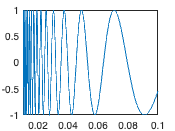

range = [0.01,0.1];
fplot(s,range)

### Nested Functions (Optional)

*Nested functions* are completely contained within another function. The primary difference between nested functions and local functions is that nested functions can use variables defined in parent functions without explicitly passing those variables as arguments.

### **Private Functions in a Subfolder **(Optional)

Like local or nested functions, private functions are accessible only to functions in a specific location. However, private functions are not in the same file as the functions that can call them. Instead, they are in a subfolder named `private`. Private functions are available only to functions in the folder immediately above the `private` folder. Use private functions to separate code into different files, or to share code between multiple, related functions.